# Paper3: 1st test - network architecture

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
DataFolder3 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3TestingKernelData-RealLGN/']; % V1D2

addpath(DataFolder3)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo090324/']; % V1D2
close all

## 2. Test for different x for E and I; yE and yI kept as 1 -- All killed are folded back

first get basic function information

Too time comsuming. --->> using HPC

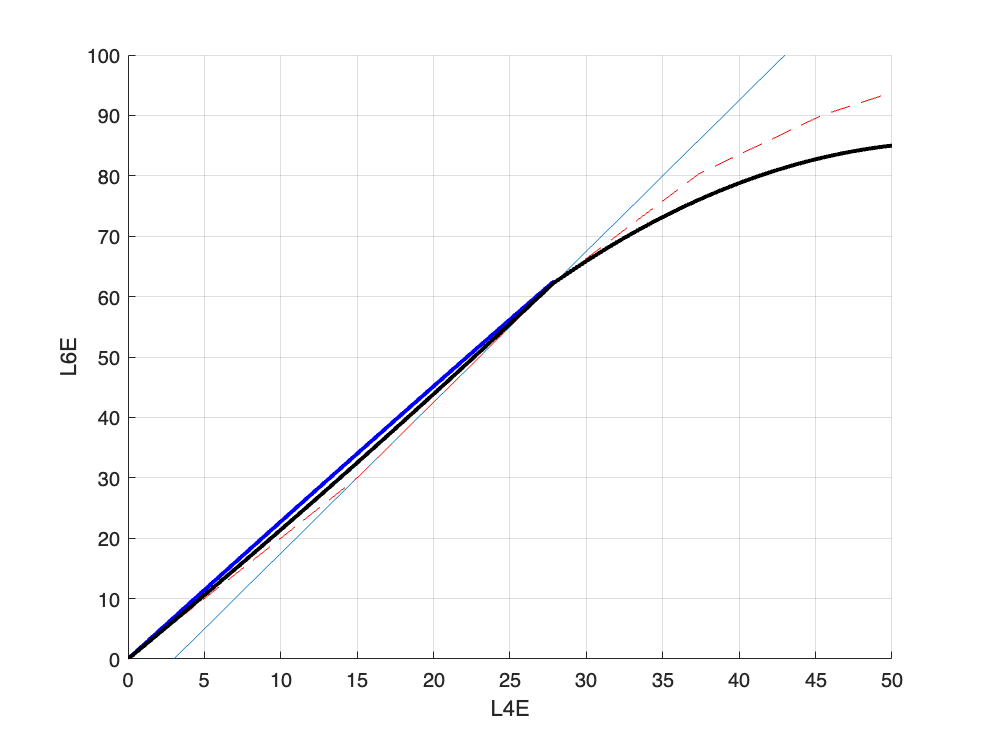

close all
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
%L6pars{2} = {2.5,3,[28; 31.5;37.4],[62.5; 69; 80.4],'quadratic'};
%L6pars{2} = {2.5,3,62.5,86,80.4,106,90};
L6pars{5} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,32.5],[28 32 50],[69 85]}};

L6pars{4} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,34],[28 32 50],[69 85]}};
L6pars{3} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 28],[1,34]}};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20],{[8 21.5 25],[0.04,0]}}}; % {[10 20 25],[0.04,0.02]}
L6pars{1} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20]}};
%L6pars{1} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
xx = 0:0.1:50;
yy = L6Convert(xx, L6pars{1});
zz = L6Convert(xx, L6pars{2});
ww = L6Convert(xx, L6pars{4});
rr = L6Convert(xx, L6pars{5});
figure(99)
hold on
grid on
plot(xx,2.5*(xx-3))
plot(xx,yy,'r--')
%plot(xx,zz,'k-','LineWidth',2)
plot(xx,ww,'b-','LineWidth',2)
plot(xx,rr,'k-','LineWidth',2)

ylim([0 100])
xlabel('L4E');ylabel('L6E')

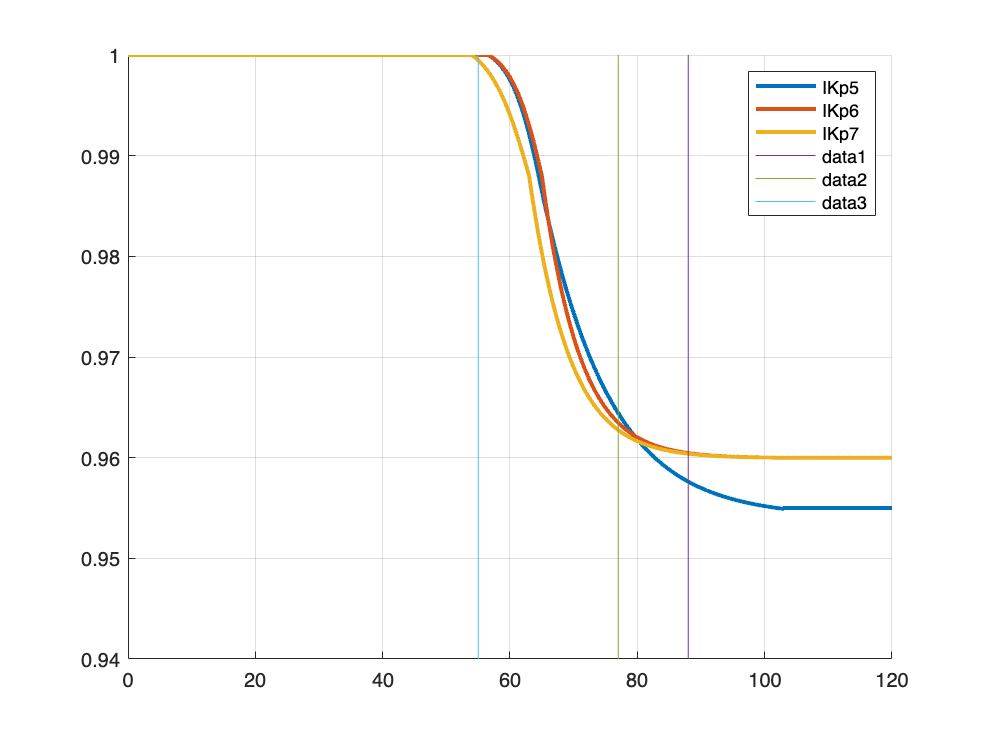


% Inhibition saturation info
IKp1.Thrsld1 = 56.6; IKp1.Thrsld2 = 68.6;
IKp1.Highist = 115;  IKp1.Slope = 0.95; % this is for new rule: multiplicative saturation
Isaturation = true;
IKp1.Mode = 'multisigmoid'; % or 'linear'
IKp1.IntaH = 5.5; IKp1.IntaL = -1;
IKp1.IntbL = 3; IKp1.IntbH = 0.5; % one side start from 3. another side start from 6

IKp2.Thrsld1 = 56.6; IKp2.Thrsld2 = 65;
IKp2.Highist = 103;  IKp2.Slope = 0.949; % this is for new rule: multiplicative saturation
IKp2.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp2.Mode = 'multisigmoid'; % or 'linear'
IKp2.IntaH = 4.5; IKp2.IntaL = -2.5;
IKp2.IntbL = 3.4; IKp2.IntbH = -0.3; % one side start from 3. another side start from 6

IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKp4.Thrsld1 = 56.6; IKp4.Thrsld2 = 65;
IKp4.Highist = 103;  IKp4.Slope = 0.9525; % this is for new rule: multiplicative saturation
IKp4.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp4.Mode = 'multisigmoid'; % or 'linear'
IKp4.IntaH = 5; IKp4.IntaL = -2.5;
IKp4.IntbL = 3.4; IKp4.IntbH = -0.3; % one side start from 3. another side start from 6

IKp5.Thrsld1 = 56.6; IKp5.Thrsld2 = 65;
IKp5.Highist = 103;  IKp5.Slope = 0.955; % this is for new rule: multiplicative saturation
IKp5.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp5.Mode = 'multisigmoid'; % or 'linear'
IKp5.IntaH = 6.3; IKp5.IntaL = -2.5;
IKp5.IntbL = 3.4; IKp5.IntbH = -0.3; % one side start from 3. another side start from 6

IKp6.Thrsld1 = 56.6; IKp6.Thrsld2 = 65;
IKp6.Highist = 103;  IKp6.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp6.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp6.Mode = 'multisigmoid'; % or 'linear'
IKp6.IntaH = 9.3; IKp6.IntaL = -2.5;
IKp6.IntbL = 3.4; IKp6.IntbH = -0.3; % one side start from 3. another side start from 6

IKp7.Thrsld1 = 54; IKp7.Thrsld2 = 63;
IKp7.Highist = 103;  IKp7.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp7.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp7.Mode = 'multisigmoid'; % or 'linear'
IKp7.IntaH = 9.3; IKp7.IntaL = -2.5;
IKp7.IntbL = 2.9; IKp7.IntbH = -0.3; % one side start from 3. another side start from 6

figure(100)
xx = 0:0.1:120;
IKpAll = {IKp1,IKp2,IKp3,IKp4,IKp5,IKp6,IKp7};
for IkpInd = 5:length(IKpAll)
[yy1,fac1] = InhMulp(xx,IKpAll{IkpInd});
hold on
plot(xx,fac1,'LineWidth',2,'DisplayName',sprintf('IKp%d',IkpInd))
end
%plot(60:100,1-(0:40)*0.05/40)
yyz = 0.94:0.01:1;
plot(88*ones(size(yyz)),yyz)
plot(77*ones(size(yyz)),yyz)
plot(55*ones(size(yyz)),yyz)
grid on
axis([0 120 0.94 1])
legend


L6parId = 5;
IkpInd = 7;
IKpUse = IKpAll{IkpInd};
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'};

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0'}; % only vertical for now
% AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','LARGER'};

## 3. Set up initial conditions

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;

Parameters of L4 kernels

MonocuFlag = true;
%ParaIx = 0;   ParaIy = 1;
TestEx = 0:0.25:1; TestEy = 0:0.25:1;
aa = length(TestEx); bb = length(TestEy);
TestNum = aa*bb;
ICTestAll = cell(TestNum,1);

TestExMat = repmat(TestEx,bb,1); TestEyMat = repmat(TestEy',1,aa);
TestExSeq = TestExMat(:); TestEySeq = TestEyMat(:);

Background

% LDEbgIC.S = 2.5*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.C = 8*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.I = 18*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1); %16
% LDEICOut = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

ICData = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang0.0.mat')]);
load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;

LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
for TestId = 1:TestNum
    ICTestAll{TestId} = LDEICOut;
end
LDEOutAll = cell(size(ICTestAll));
NANFlag = false(size(ICTestAll));
%BGFlagAllTest = cell(size(ICTestAll));

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

p = 0.50;% 1-p for the original input
EpocTest =100;
ExportFlag = 'xn';
BGflag = false(size(LDEOutAll));

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);
FuncUse = cell(length(ICTestAll),1);

AngleTestAll = 0*ones(TestNum,1); % 0:7.5:22.5; % has to be multiples of 7.5

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

lgnSF = 2.5; lgnTF = 10;
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

if strcmp(L6pars{L6parId}{end},'quadratic')
    L6Comment = sprintf('%s',L6pars{L6parId}{end})
elseif iscell(L6pars{L6parId}{end})
    L6Comment = sprintf('LowModi3');
    if length(L6pars{L6parId}{end}) == 4
        L6Comment = sprintf('LowHighQuadr5')
    end
    if iscell(L6pars{L6parId}{end}{end})
        L6Comment = sprintf('ContrTweak3');
    end
else
    L6Comment = sprintf('linear')
end

L6Comment = 'LowHighQuadr5'

IkpComment = sprintf('IKp%d',IkpInd);

## 6*6 tests

We start from 1. BG for both eyes, and 2. Vertical for both eyes. Target: BG for left and vertical for right

for TestId = 1:TestNum
    AngleInpt = AngleTestAll(TestId)

    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end

    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

AngleInpt = 0

ans = 'RunTime = 36.95'

AngleInpt = 0

ans = 'RunTime = 36.06'

AngleInpt = 0

ans = 'RunTime = 35.99'

AngleInpt = 0

ans = 'RunTime = 36.01'

AngleInpt = 0

ans = 'RunTime = 36.07'

AngleInpt = 0

ans = 'RunTime = 36.29'

AngleInpt = 0

ans = 'RunTime = 36.38'

AngleInpt = 0

ans = 'RunTime = 36.29'

AngleInpt = 0

ans = 'RunTime = 36.31'

AngleInpt = 0

ans = 'RunTime = 36.41'

AngleInpt = 0

ans = 'RunTime = 36.28'

AngleInpt = 0

ans = 'RunTime = 36.33'

AngleInpt = 0

ans = 'RunTime = 36.44'

AngleInpt = 0

ans = 'RunTime = 36.31'

AngleInpt = 0

ans = 'RunTime = 36.31'

AngleInpt = 0

ans = 'RunTime = 36.31'

AngleInpt = 0

ans = 'RunTime = 36.42'

AngleInpt = 0

ans = 'RunTime = 36.33'

AngleInpt = 0

ans = 'RunTime = 36.24'

AngleInpt = 0

ans = 'RunTime = 36.38'

AngleInpt = 0

ans = 'RunTime = 36.37'

AngleInpt = 0

ans = 'RunTime = 36.23'

AngleInpt = 0

ans = 'RunTime = 36.36'

AngleInpt = 0

ans = 'RunTime = 36.41'

AngleInpt = 0

ans = 'RunTime = 36.26'

load all precomputed domains

    L4EmeshXAll = cell(size(DomList));
    L4ImeshYAll = cell(size(DomList));
    LDEFrfuncAll = cell(size(DomList));
    for DomInd = 1:length(DomList)
        FuncTemp = load(sprintf('Func200%s-%s-Ang%s-SF%.1fTF%d-%s.mat',...
            DataPt,Comment,AngPrint,lgnSF,lgnTF,DomList{DomInd}),...
            'LDEFrfunc','L4EmeshX','L4ImeshY');
        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
    end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

    LGNlist = 5; L6list = 33;
    OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

    %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
    if MonocuFlag
        OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;
        SaveStr = ['Mono' Comment L6Comment IkpComment];
    else
        SaveStr = ['Bino' Comment L6Comment IkpComment];
    end

L6 kernel

    L6ConvSig = 0.75;
    L6ConvTruc = 1.5/(L6ConvSig);
    Kersize = floor(2*L6ConvSig*L6ConvTruc);
    if Kersize<=0
        Kersize= 2; % at least 1
    end
    [x,y] = meshgrid(1:Kersize,1:Kersize);
    c = Kersize/2;
    exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
    L6Kernel = exp(-exponent);
    L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
    L6Kernel = L6Kernel + ...
        L6Kernel(end:-1:1,:) + ...
        L6Kernel(:,end:-1:1) + ...
        L6Kernel(end:-1:1,end:-1:1);%symmetrize
    L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
    L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
    L6Kernel(2,2) = 0.3;

LGN and L6 are blurred 

    N_HCold = 3; % shrink to 2*2
    FigOn = false;
    LGNsmear = n_S_HC*0.2;
    TruncLGN = 1;
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
        N_HCold,n_S_HC,LGNsmear,TruncLGN,FigOn);

    if ~MonocuFlag
        LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
    end

    PixLGNCtgr = LGNIndSpat_Rec(...
        LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

    % symmetrize !! This is actually trick, so I do it ad hoc
    PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

    MirInd = logical(MirInd);
    CtgrOrder = [2,1;3,4]; % for lower left HC
    CtgrOrderUse = rot90(CtgrOrder,RotInd);
    if MirInd
        %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
        CtgrOrderUse = flip(CtgrOrderUse,1);
    end
    CtgrOrderReadout = ...
        [CtgrOrderUse(1,2);
        CtgrOrderUse(1,1);
        CtgrOrderUse(2,1);
        CtgrOrderUse(2,2)];
    %    for Ctgr = 1:4
    %         PixL6Ctgr(:,Ctgr) = ...
    %             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
    %         PixLGNCtgr(:,Ctgr) = ...
    %             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
    %    end

    % let's implement something cheap now for 45 deg
    PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);
    if BGflag(TestId)
        PixLGNCtgr(:,1:4) = 0;
        PixLGNCtgr(:,5) = 1;
    end

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

    ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
    ParaIx = ParaEx;   ParaIy = ParaEy;

    C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

    Conn_Reduc_Test = 5;
    Reduc_S = Conn_Reduc_Test*(1-CplxR); Reduc_C = Conn_Reduc_Test*CplxR;
    P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
    P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
    P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
    P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
    %
    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

    tic
    ICUse = ICTestAll{TestId}; %
    IniTest = ICUse;
    %IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    %IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    %IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);


start iteration

    [LDEOutAll{TestId},~,~,~,~,FuncUse{TestId},...
        NANFlag(TestId)] = ...
        LDEIteration_135FuncMain_CombDom_RealLGNL6(...
        PixLGNCtgr,L6Kernel,IniTest,p,L6pars{L6parId}, EpocTest,...
        C_SS_meanU,C_CS_meanU,C_IS_mean,...
        C_SC_meanU,C_CC_meanU,C_IC_mean,...
        C_SI_mean, C_CI_mean, C_II_mean,...
        L4SEp, L4SIp, ...
        L4CEp, L4CIp, ...
        L4IEp, L4IIp, ...
        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
        N_HCOutY,NPixX,NPixY,Isaturation,'xn',EKpUse,IKpUse)  ;
    LDEEquv = LDEOutAll{TestId}{end};

    RunTime = toc;
    sprintf('RunTime = %.2f',RunTime)

    if ~NANFlag(TestId)
        for EpcInd = 1:EpocTest+1
            LDEPertRslt = LDEOutAll{TestId}{EpcInd};
            SDiff = LDEPertRslt.S - LDEEquv.S;
            SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            CDiff = LDEPertRslt.C - LDEEquv.C;
            CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            IDiff = LDEPertRslt.I - LDEEquv.I;
            IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);

            L2Diff_OneStepAll(TestId,EpcInd) = ...
                sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
            DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
        end
    end
end

    Comment below if don't need to save data (usually for setting up new NESSs) 

SaveStrUse = sprintf('%s_Ag%d_RealLGNSF%.1fTF%d_Ereduc%d',...
    SaveStr,AngleTestAll(1),lgnSF,lgnTF,Conn_Reduc_Test);

save([SaveToFolder sprintf('SameEIKer-EIDep_%s.mat',SaveStrUse)],...
    'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','TestEx','TestEy')

## Figure 6*6

SaveStrUse = sprintf('%s_Ag%d_RealLGNSF%.1fTF%d_Ereduc%d',...
    SaveStr,AngleTestAll(1),lgnSF,lgnTF,Conn_Reduc_Test);

load([SaveToFolder sprintf('SameEIKer-EIDep_%s.mat',SaveStrUse)],...
    'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','TestEx','TestEy')

Fig3 = figure("Name",sprintf('TestKernel_SameEIKer_%s',SaveStrUse),...
    'units','normalized','outerposition',[0,0,1,1]);
ha = tight_subplot(5,5,[.04 .015],[.05 .05],[.05 .1]);
for TestId = 1:TestNum
    if NANFlag(TestId)
        continue
    end
    axes(ha(TestId));
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    %title(sprintf('P(cross)=%.1f, P(return)=%.2f',...
    %    TestExSeq(TestId),(1-TestExSeq(TestId)) * TestEySeq(TestId)),...
    %    'Interpreter','tex','FontSize',15)
    axes(ha(TestId));
    axis([0.5 20.5 10.5 30.5])
    axis square
    caxis([3 40]);
    colorbar off
    if mod(TestId,5) == 0
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
        set(cbr1,'FontSize',13)
    end
    %     subplot 122
    %     ShowField_Rec(LDEOutAll{TestId}{end}.I,...
    %         1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
    %     title("FrI")

end

Save and Print Figs

FigName1 = sprintf('TestKernel_SameEIKer-EIDep_%s',SaveStrUse);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

Plot Kernel figures: some samples

figure
for SubPlotInd = 1:10
    subplot(2,5,SubPlotInd)
    ShowField_Rec(C_SI_mean(800+SubPlotInd,:)',...
        1:N_HCOutX*NPixX*N_HCOutY*NPixY, N_HCOutX*NPixX, N_HCOutY*NPixY)
    title(sprintf('%d; sum = %.1f',800+SubPlotInd, full(sum(C_SI_mean(800+SubPlotInd,:),'all'))))
    caxis([0 6])
end

LGN/L6 kernels

figure
subplot 151
ShowField_Rec(PixL6Ctgr(:,1),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 152
ShowField_Rec(PixL6Ctgr(:,2),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 153
ShowField_Rec(PixL6Ctgr(:,3),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 154
ShowField_Rec(PixL6Ctgr(:,4),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 155
ShowField_Rec(PixL6Ctgr(:,5),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)